This live-script runs solvers for the 1D acoustics equations via staggered grid FD methods.

In particular, the output pressure field is only stored at a single or multiple receivers.

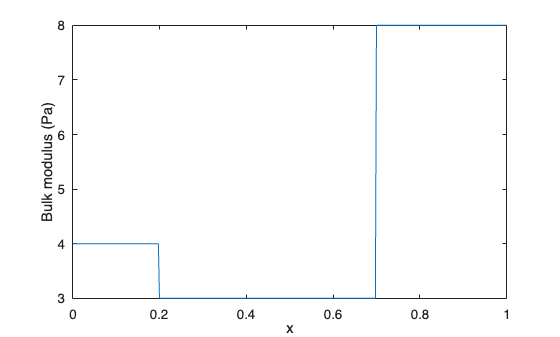

clear
close all
clc

% Computational space grids
dom_x = [0,1];
Nx = 401;

gsp_primal = GridSpace1D( Grid1DUnifPrimal(dom_x,Nx) );
gsp_dual   = GridSpace1D( Grid1DUnifDual(gsp_primal.x) );

% Medium parameters
medium = AcousticMedium1D.layered( ...
    BetaValues=[0.25,0.5,1], ...
    KappaValues=[4,3,8], ...
    Domain=dom_x, ...
    RelativeWidths=[0.2,0.5,0.3]);
[kappa,beta,wspeed,cMax] = sampleMedium1D(gsp_primal,medium);

kappa.plot;

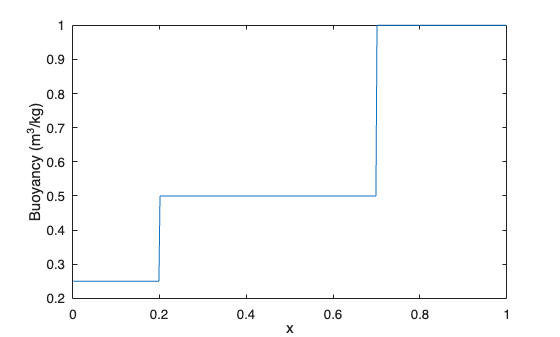

beta.plot;

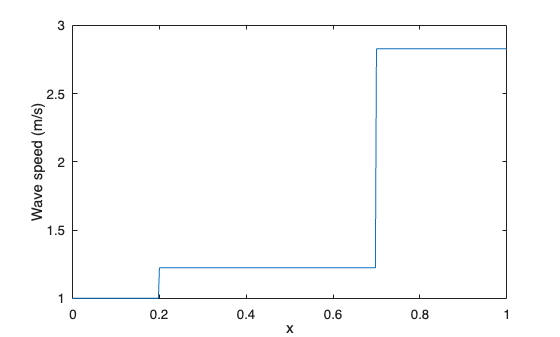

wspeed.plot;


% Computational time grid
dom_t = [0,1];
CFL = 0.9;
dt = CFL*(6/7)*gsp_primal.h/cMax;
Nt = ceil(diff(dom_t)/dt)+1;
dt = diff(dom_t)/(Nt-1); %recomputing dt to ensure time length is divisible by dt
times = dom_t(1):dt:dom_t(2);

% Multipole point source
xc = 0.8;
tc = 0.2;
fpeak = 10;

monopole = MultipoleTerm1D(xc,0,...
    @(t) RickerWave(t,tc,fpeak),...
    TargetField="pressure");

dipole = MultipoleTerm1D(xc,1,...
    @(t) RickerWave(t,tc,fpeak),...
    Amplitude=gsp_primal.h, ...
    TargetField="pressure");

mps = MultipoleSeries1D( ...
    [monopole,dipole], ...
    ApproximationOrder=4);
source = mps.discretize(gsp_primal,gsp_dual);

% Initializing PML
pml = PML1D( ...
    WidthLeft=0.2, ...
    WidthRight=0.2, ...
    ReflectionCoefficient=1e-6, ...
    PolynomialDegree=3);

% Zero initial conditions
p0 = @(x) zeros(size(x));
v0 = @(x) zeros(size(x));

% Output times
times_out = linspace(dom_t(1),dom_t(2),81);


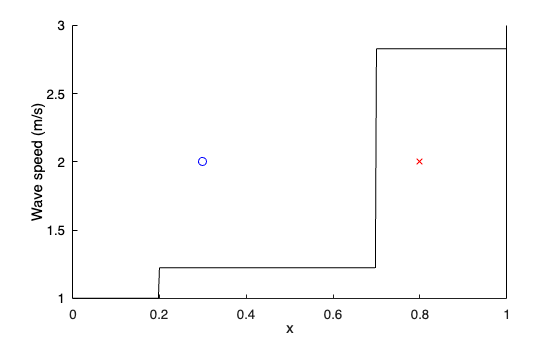

% Case with a single receiver
x_rcv = 0.3;
gsp_single = GridSpace1D( Grid1D(dom_x,x_rcv) );

plotAcqGeo(wspeed,mps,gsp_single);

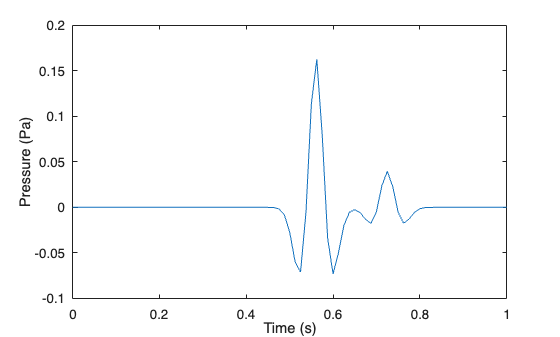


% Initialize solver
solver_single = AcousticSolver1D_PML( ...
    gsp_primal,times, ...
    gsp_single,times_out, ...
    medium, pml, ...
    SpatialOrder=4);

% Run solver
[P_single,~] = solver_single.solve(p0,v0,Source=source);

% Plotting results
P_single.plotTimeSeries;

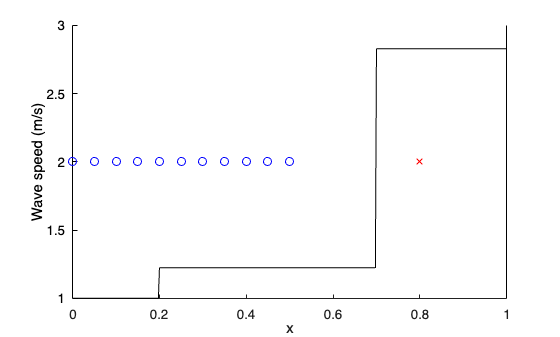

% Cases with multiple receivers
gsp_mlt = GridSpace1D( Grid1DUnifPrimal([0,0.5],11) );

plotAcqGeo(wspeed,mps,gsp_mlt);

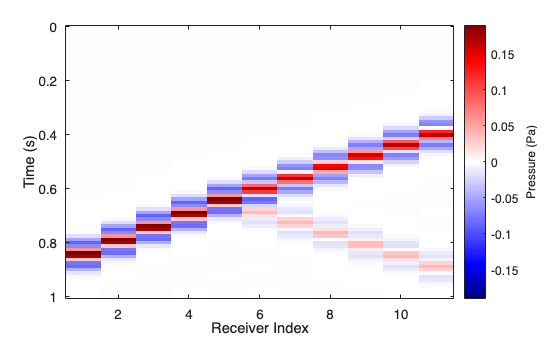


% Initialize solver
solver_mlt = AcousticSolver1D_PML( ...
    gsp_primal,times, ...
    gsp_mlt,times_out, ...
    medium, pml, ...
    SpatialOrder=4);

% Run solver
[P_mlt,~] = solver_mlt.solve(p0,v0,Source=source);

% Plotting results
P_mlt.plotTimeSeries;